# Continue training a previous DAGNetwork

### Import trained lesionNet

% change the filename to the path of the .mat file 
%           (must include imageDatastores)
load lesionNet_prev.mat

lgraph = layerGraph(lesionNet);

### Set training options

Stochastic Gradient Descent with Momentum

Learning rate = 0.001

miniBatchSize = 64;
validationsPerEpoch = 5;
validationPatienceEpochs = 3;

iterationsPerEpoch = floor(numel(trainds.Files)/miniBatchSize);
validationFrequency = floor(iterationsPerEpoch/validationsPerEpoch);
validationPatience = validationsPerEpoch * validationPatienceEpochs;

options = trainingOptions("sgdm", ...
    "InitialLearnRate", 0.001, ...
    'MiniBatchSize',128/2,"Shuffle", "every-epoch", ...
    'MaxEpochs', 30, ...
    'Plots','training-progress',"L2Regularization", 1e-4, ... 
    "ValidationData", valds, "ValidationFrequency",validationFrequency, ...
    "OutputNetwork","best-validation-loss", "ValidationPatience", validationPatience);

### Train the neural network

lesionNet = trainNetwork(trainds, lgraph, options);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:41 |       84.38% |       76.97% |       0.3886 |       0.6564 |          0.0010 |
|       1 |          50 |       00:01:32 |       79.69% |              |       0.4663 |              |          0.0010 |
|       1 |         100 |       00:02:24 |       84.38% |              |       0.3198 |              |          0.0010 |
|       1 |         150 |       00:03:17 |       84.38% |              |       0.3752 |   

Save trained model to device

save lesionNet_prev.mat lesionNet options balTrainImds valImds trainds valds;

#### Evaluate network on Validation set

preds = classify(lesionNet, valds);

valTrue = valImds.Labels;
valAccuracy = nnz(preds == valTrue)/numel(preds)

valAccuracy = 0.8092

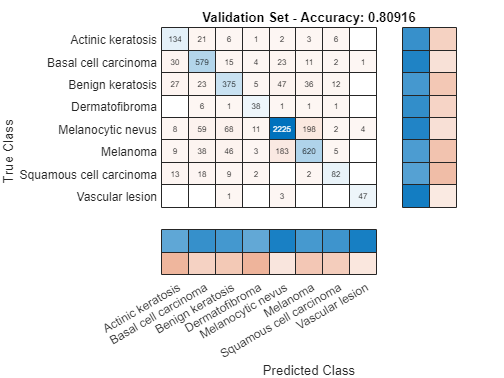

confusionchart(valTrue, preds, 'RowSummary','row-normalized', 'ColumnSummary','column-normalized','Title',"Validation Set - Accuracy: " + string(valAccuracy));

### Visualize failed predictions

failedPredictions = find(preds~=valTrue);
num_fail = numel(failedPredictions);
failedSample = 797;
if ~isempty(failedPredictions)
    imshow(readimage(valImds,failedPredictions(failedSample)), 'InitialMagnification', 100);
    title("Actual: " + string(valTrue(failedPredictions(failedSample))) + "// Predicted: " + string(preds(failedPredictions(failedSample))))
end

### Visualize correct predictions

correctPredictions = find(preds==valTrue);
num_correct = numel(correctPredictions);
correctSample = 789;
if ~isempty(correctPredictions)
    imshow(readimage(valImds,correctPredictions(correctSample)), 'InitialMagnification', 100);
    title("Actual: " + string(valTrue(correctPredictions(correctSample))) + "// Predicted: " + string(preds(correctPredictions(correctSample))))
end